# Segundo parcial

## Cargar datos

Cargar los datos del archivo "E2_SegundoParcial_data.mat"

load("./E2_SegundoParcial_data.mat")

## Problema 1

- Graficar el campo "Water _Level..." de la tabla "IrishTide" contra el tiempo. 

- Hacer una inspección visual y estimar la frecuencia de las componentes espectrales que contiene la señal. Toma en cuenta que son mareas y que están gobernadas por eventos bien caracterizados.

El resultado debe ser similar a:

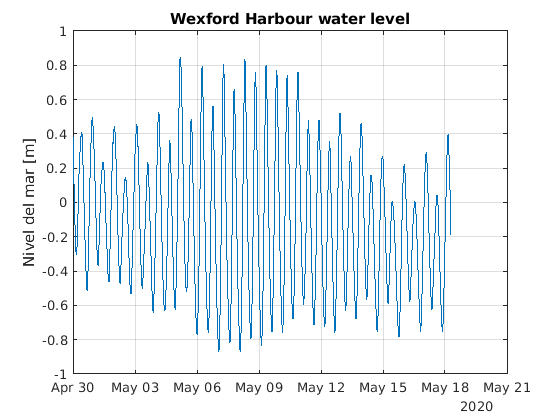

figure
plot(IrishTide.DateTime,IrishTide.Water_Level_OD_Malin)

title("Wexford Harbour water level")
ylabel("Nivel del mar [m]")
grid on

- Extraer el vector de densidad de potencia espectral $P_{xx}$ y  el eje de frecuencias $f$ del campo "Water _Level...", que se encuentra en la tabla de "IrishTide". Recordar que siempre debemos tener a la mano la cantidad de muestras $N
$ y la frecuencia de discretización  $f\  [Hz]$ a la mano.

- Graficar el eje y en escala de Power dB, con el eje horizontal limitado entre 0 y 0.1.

El resultado debe ser similar a:

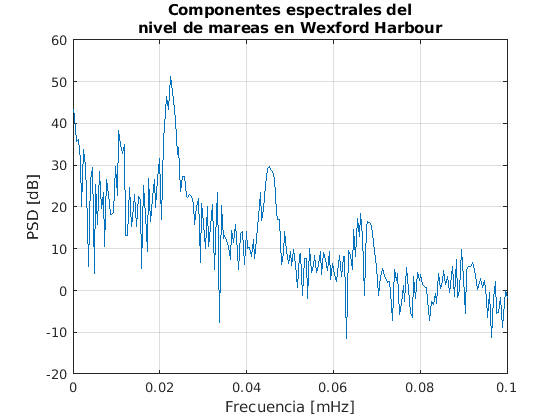

N=numel(IrishTide.Water_Level_OD_Malin);
fs_irish=1/(5*60);
[Pxx,f]=periodogram(IrishTide.Water_Level_OD_Malin,rectwin(N),[],fs_irish);

figure
plot(f.*1000,pow2db(Pxx))
xlabel("Frecuencia [mHz]")
ylabel("PSD [dB]")
title(["Componentes espectrales del";"nivel de mareas en Wexford Harbour"])
xlim([0 0.1])
grid on

- Calcular $log_{10}$ a $f$ y $P_{xx}$ con la función *log10(). *Guardarlas como variables *f_log* y *Pxx_log*.

- Quitar el primer elemento de *f_log* y *Pxx_log.*Esto es necesario porque el primer elemento de *f_log*  es *-inf* y nos causará problemas después.

- Hacer un ajuste lineal entre *Pxx_log *y* f_log. *

- Graficar 1) *Pxx_log vs f_log. *2) El ajuste lineal. El $\alpha$ es la pendiente del ajuste.

El resultado debe verse como:

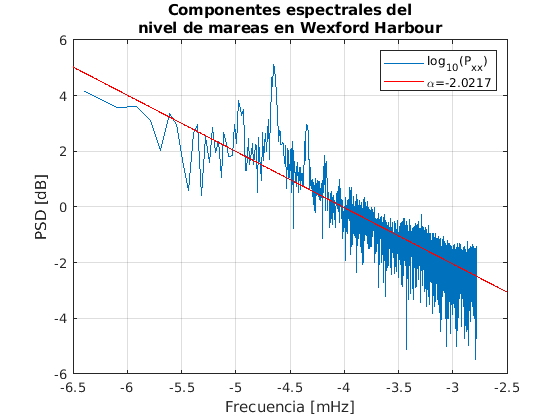

La pendiente de la línea representa la ley de potencia para el contenido espectral del ruido de fondo en la señal. Discutir:

- A juzgar por el valor de $\alpha$, ¿Qué color de ruido de fondo tenemos?

- ¿Qué podrías comentar sobre la autenticidad de los datos?

 Recordar la presentación sobre ruido.

f_log=log10(f);
Pxx_log=log10(Pxx);
f_log(1)=[];
Pxx_log(1)=[];

[Pxx_fit,gof]=fit(f_log,Pxx_log,'poly1')

Pxx_fit =      Linear model Poly1:
     Pxx_fit(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      -2.022  (-2.062, -1.982)
       p2 =      -8.111  (-8.241, -7.981)

gof = struct with fields:
           sse: 1.3126e+03
       rsquare: 0.7043
           dfe: 4094
    adjrsquare: 0.7042
          rmse: 0.5662


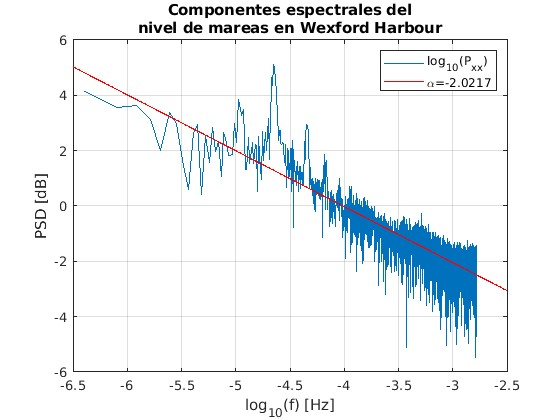


figure
plot(f_log,Pxx_log)
hold on
plot(Pxx_fit)
hold off
xlabel("log_{10}(f) [Hz]")
ylabel("PSD [dB]")
title(["Componentes espectrales del";"nivel de mareas en Wexford Harbour"])
grid on
legend("log_{10}(P_{xx})","\alpha="+Pxx_fit.p1)

- Hacer una segunda vizualización sustituyendo el eje de frecuencias $f$ por uno de periodo $T
$.  Recordar que $T [s]=1/f $.

- Convertir $T[s]\rightarrow\ T[Horas] $

- Usar la función *semilogx()* en lugar de *plot()* para generar la visualización con eje horizontal logarítmico.

- Encontrar las 3 componentes más sobresalientes

El resultado debe verse así

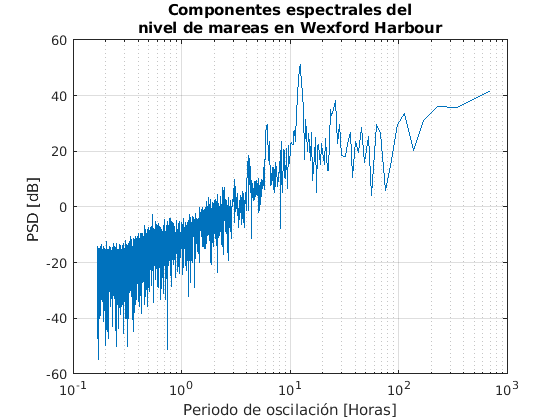

T=1./f;
T=T./(3600);

figure
semilogx(T,pow2db(Pxx))
xlabel("Periodo de oscilación [Horas]")
ylabel("PSD [dB] ")
title(["Componentes espectrales del";"nivel de mareas en Wexford Harbour"])
grid on

- Usar findpeaks() para encontrar automáticamente la  señal más sobresaliente.

- Graficar la señal mas sobresaliente

El resultado debe verse como: 

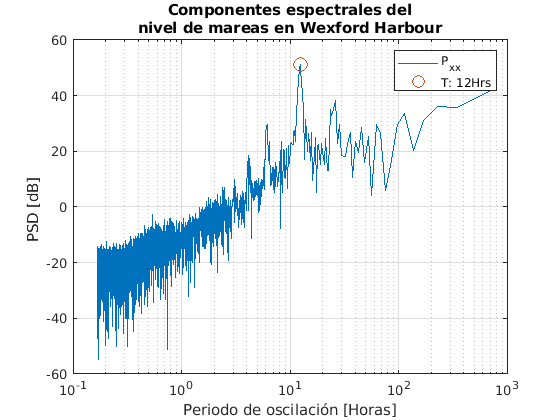

[pks,locs]=findpeaks(pow2db(Pxx),"NPeaks",1,"MinPeakProminence",10,"MinPeakHeight",40);

figure
semilogx(T,pow2db(Pxx))
hold on
semilogx(T(locs),pow2db(Pxx(locs)),'o','MarkerSize',10)
hold off
xlabel("Periodo de oscilación [Horas]")
ylabel("PSD [dB] ")
title(["Componentes espectrales del";"nivel de mareas en Wexford Harbour"])
grid on
legend("P_{xx}","T: "+floor(T(locs))+"Hrs")

## Problema 2

- Probar desde la definición de la transformada de Fourier $F$ que:


$$F[ cos(\omega_0t)]=\pi\delta(\omega-\omega_0)+\pi\delta(\omega+\omega_0)$$



$$F[ sin(\omega_0t)]=\frac{\pi}{j}\delta(\omega-\omega_0)-
\frac{\pi}{j} \delta(\omega+\omega_0)$$


Recordar la definición de $cos(\omega_0t)$y $sin(\omega_0t)$ en forma de exponenciales complejas. Auxíliate de las tablas de resultados comunes en la presentación de transformada de Fourier.

-   Usar las funciones simbólicas para hacer la misma operación del punto anterior. Nota: $\delta(t)$=*dirac(t)*

La salida se ve así:

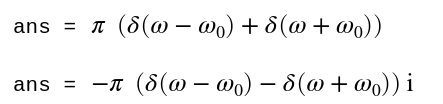

syms t omega_0 omega
fourier(cos(omega_0*t),t,omega)

$$ans = \pi \,\left(\delta (\omega -\omega_{0})+\delta (\omega +\omega_{0})\right)$$

fourier(sin(omega_0*t),t,omega)

$$ans = -\pi \,\left(\delta (\omega -\omega_{0})-\delta (\omega +\omega_{0})\right)\,\mathrm{i}$$

## Problema 3

- Escuchar el audio *bird*

- Obtener un espectrograma como el siguiente. Recuerda siempre tener a la mano las variables *N* y *N_spect.*

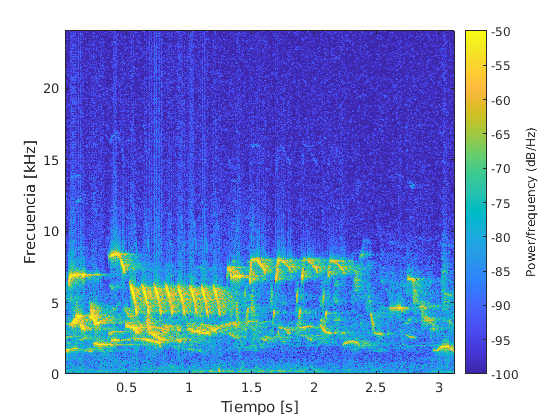

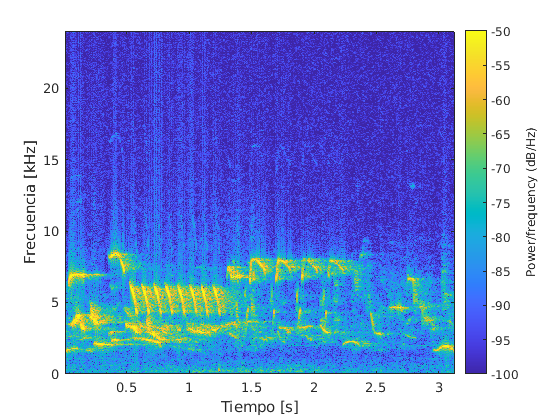

N=round(numel(bird));
N_spec=round(N/200);

figure
spectrogram(bird,rectwin(N_spec),[],[],fs_bird,'Yaxis')
caxis([-100 -50])
xlabel("Tiempo [s]")
ylabel("Frecuencia [kHz]")

- Crear un filtro pasa alta, pasa bajo y pasa banda que acepten las siguientes bandas:

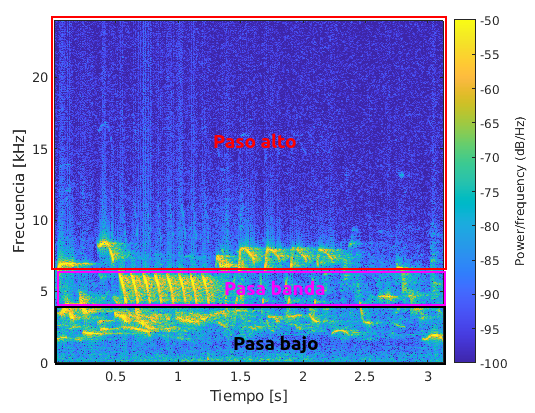

- Filtrar las señales y mostrar el espectrograma. Los resultados se ven así:

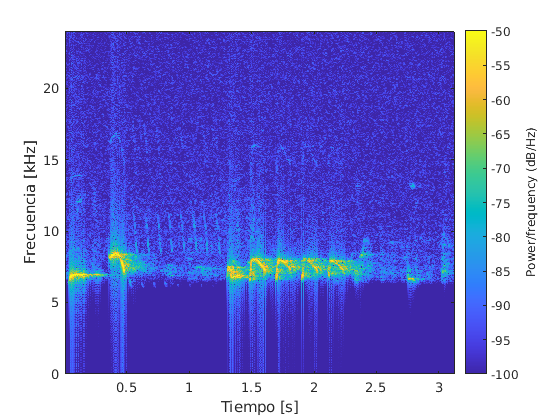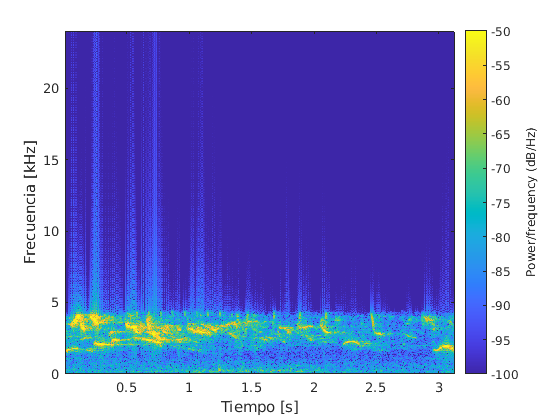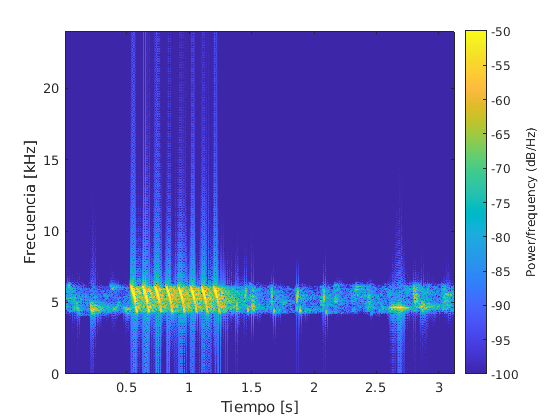

Pasa Alto//Pasa bajo// Pasa banda

- Escuchar los resultados y opinar al respecto

HP_filt=designfilt('highpassfir', 'StopbandFrequency', 6000, 'PassbandFrequency', 6500, 'StopbandAttenuation', 60, 'PassbandRipple', 1, 'SampleRate', 48000);
LP_filt=designfilt('lowpassfir', 'PassbandFrequency', 4000, 'StopbandFrequency', 4500, 'PassbandRipple', 1, 'StopbandAttenuation', 60, 'SampleRate', 48000);
BP_filt=designfilt('bandpassfir', 'StopbandFrequency1', 4000, 'PassbandFrequency1', 4500, 'PassbandFrequency2', 6000, 'StopbandFrequency2', 6500, 'StopbandAttenuation1', 60, 'PassbandRipple', 1, 'StopbandAttenuation2', 60, 'SampleRate', 48000);


bird_HP=filter(HP_filt,bird);
bird_LP=filter(LP_filt,bird);
bird_BP=filter(BP_filt,bird);

figure
spectrogram(bird_BP,rectwin(N_spec),[],[],fs_bird,'Yaxis')
caxis([-100 -50])
xlabel("Tiempo [s]")
ylabel("Frecuencia [kHz]")

sound(bird_HP,fs_bird)
sound(bird_LP,fs_bird)
sound(bird_BP,fs_bird)